# Actividad 4 | Robot Cartesiano 3 GDL

Oscar Ortiz Torres A01769292

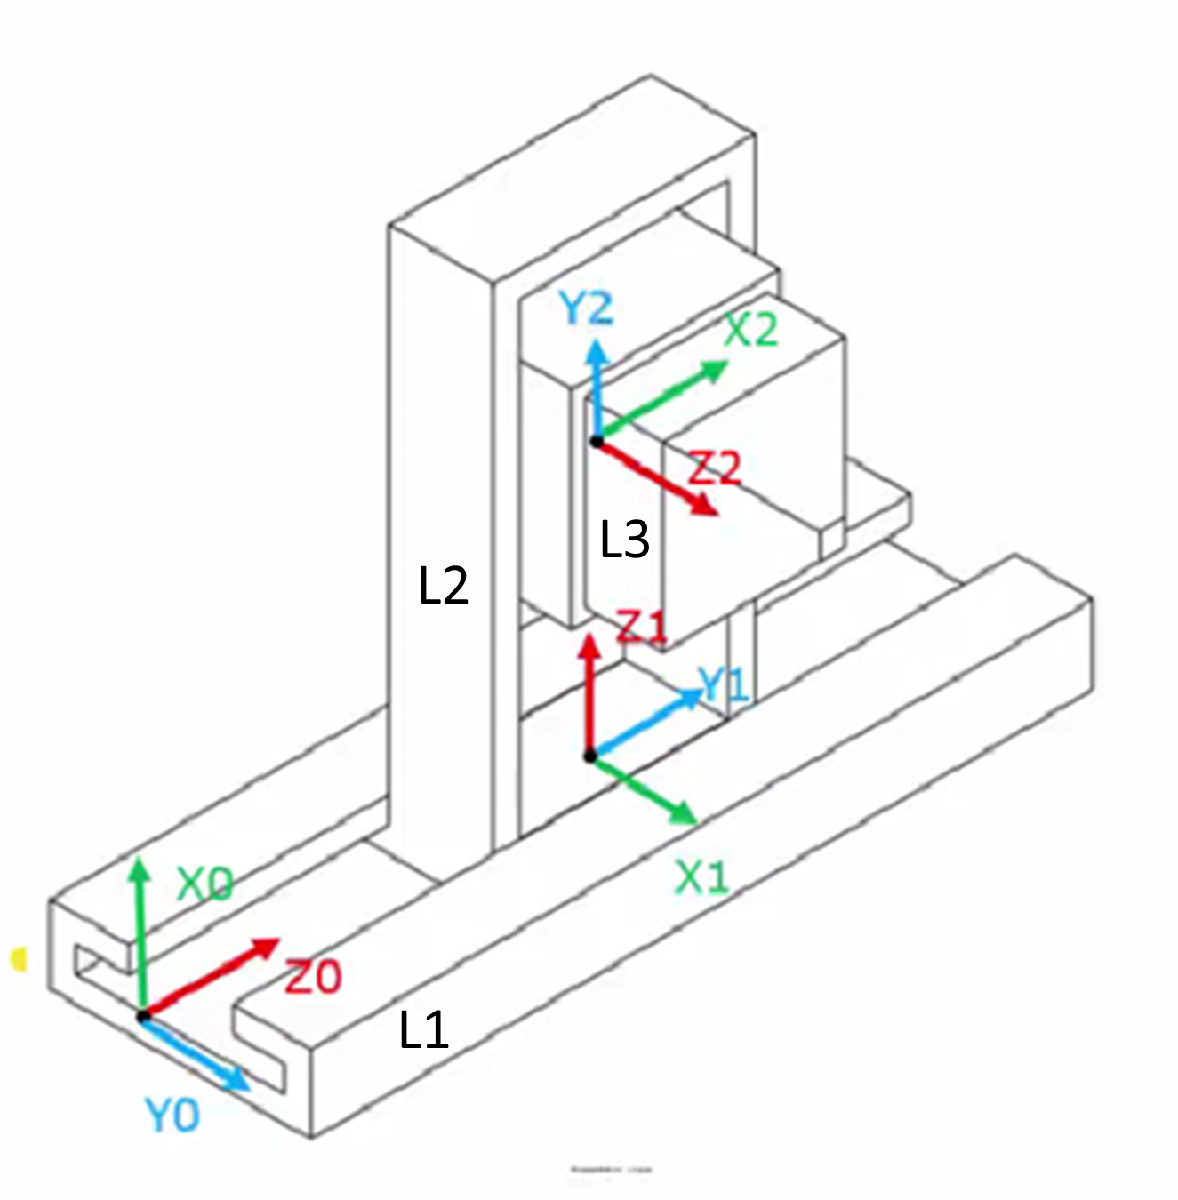

% Limpieza de pantalla
clear all
close all
clc

Se declaran las distancias de los 3 eslabones prismáticos

% Declaración de variables simbolicas
syms l1(t) l2(t) l3(t) t

% Configuración del robot, 1 para junta prismática
RP = [1 1 1];

% Creación del vector de coordenadas articulares
Q = [l1 l2 l3];

% Creación del vector de velocidades generalizadas
Qp = diff(Q, t);

% Número de grados de libertad
GDL = size(RP, 2);
GDL_str = num2str(GDL);

## Eslabón 1

El movimiento solo existe en el eje Z, por lo que la magnitud del desplazamiento se queda como constante en esa posición del vector de posición.

% Posición de la articulación 1 respecto a 0
P(:,:,1) = [
            0;
            0;
            l1
           ];

Para pasar del sistema de coordenadas 0 al 1 se necesitan aplicar dos rotaciones distintas, la primera de +90° en el eje Y y después, bajo el nuevo sistema de referencia, una de +90° en el eje Z. Ambas rotaciones son positivas debido a la regla de la mano derecha.

% Matriz de rotación de la junta 1 respecto a la 0
R(:,:,1) = rotY(90)*rotZ(90);

## Eslabón 2

El movimiento solo existe en el eje Z, por lo que la magnitud del desplazamiento se queda como constante en esa posición del vector de posición

% Posición de la articulación 2 respecto a 1
P(:,:,2) = [
            0;
            0;
            l2
           ];

Para pasar del sistema de coordenadas 1 al 2 se necesitan aplicar dos rotaciones distintas, la primera de +90° en el eje X y después, bajo el nuevo sistema de referencia, una de +90° en el eje Y. Ambas rotaciones son positivas debido a la regla de la mano derecha.

% Matriz de rotación de la junta 2 respecto a la 1
R(:,:,2) = rotX(90)*rotY(90);

## Eslabón 3

El movimiento solo existe en el eje Z, por lo que la magnitud del desplazamiento se queda como constante en esa posición del vector de posición

% Posición de la articulación 2 respecto a 1
P(:,:,3) = [
            0;
            0;
            l3
           ];

Al no existir un nuevo sistema de coordenadas al cual llegar desde el sistema 2, me mantiene la rotación natural de la junta prismática del eje Z, siendo de 0°, obteniendo una matriz identidad.

% Matriz de rotación de la junta 2 respecto a la 1
R(:,:,3) = rotZ(0);

## Matrices

% Creación de vector de ceros
vector_zeros = zeros(1,3);

% Inicialización de las amtrices de Transformación Homogenea locales
A(:, :, GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de las amtrices de transformación Homogenea globales
T(:,:,GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de los vectores de posición vistos desde el marco de
% referencia inercial
PO(:,:,GDL) = P(:,:,GDL);

% Inicialización de las matrices de rotación vistas desde el marco de
% referencia inercial
RO(:,:,GDL) = R(:,:,GDL);

for i = 1:GDL
    i_str = num2str(i);

    % Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([ ...
                         R(:,:,i)       P(:,:,i); ...
                         vector_zeros   1 ...
                        ]); A(:,:,i)

    % Globales
    try
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i); % Caso específico cuando i=1 nos marcaría error en try
    end

    %disp(strcat('Matruz de Transformación global T', i_str));
    T(:,:,i) = simplify(T(:,:,i));

    % Obtención de la matriz de rotación "RO" y el vector de traslación PO
    % de la matriz de transformación homogenea global T(:,:, GDL)
    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
end

Matriz de Transformación local A1


$$ans = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A2


$$ans = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A3


$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

disp('Matriz de Transformación global'); T(:,:,GDL)

Matriz de Transformación global


$$ans = \left(\begin{array}{cccc} 0 & 1 & 0 & l_{2}\left(t\right)\\ 0 & 0 & 1 & l_{3}\left(t\right)\\ 1 & 0 & 0 & l_{1}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### Jacobiano lineal y angular de forma analítica

% Inicialización de jacobianos analíticos
Jv_a(:,GDL) = PO(:,:,GDL); % Lineal 
Jw_a(:,GDL) = PO(:,:,GDL); % Angular

for k = 1:GDL
    if(RP(k) == 0)
        % Para las articulaciones rotacionales
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL) - PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0 0 1], PO(:,:,GDL)); % Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k) = [0 0 1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
    elseif(RP(k) == 1)
        % Para las articulaciones prismáticas
        try
            Jv_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = [0,0,1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
            Jw_a(:,k) = [0 0 0];
    end
end


## Despliegue

El vector de velocidad lineal representa el movimiento de las 3 juntas del robot respecto al sistema de coordenadas 0, demostrando que las tranformaciones aplicadas a cada eslabón fue correcta, ya que el "l1" se mueve en Z, el "l2" en X y el "l3" en Y.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); V = simplify(Jv_a * Qp')

Velocidad lineal obtenida mediante el Jacobiano lineal


$$V(t) = \left(\begin{array}{c} \bar{\frac{\partial }{\partial t}l_{2}\left(t\right)}\\ \bar{\frac{\partial }{\partial t}l_{3}\left(t\right)}\\ \bar{\frac{\partial }{\partial t}l_{1}\left(t\right)} \end{array}\right)$$

En el caso del vector de velocidad angular, se representa vacio (lleno de ceros) al no existir rotación alguna en los ejes del sistema.

disp('Velocidad angular obtenida mediante el Jacobiano angular'); W = simplify(Jw_a * Qp')

Velocidad angular obtenida mediante el Jacobiano angular


$$W(t) = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

## Funciones de rotacion

function r_x = rotX(th)
    r_x = [1 0 0; 0 cosd(th) -sind(th); 0 sind(th) cosd(th)];
end

function r_y = rotY(th)
    r_y = [cosd(th) 0 sind(th); 0 1 0; -sind(th) 0 cosd(th)];
end

function r_z = rotZ(th)
    r_z = [cosd(th) -sind(th) 0; sind(th) cosd(th) 0; 0 0 1];
end